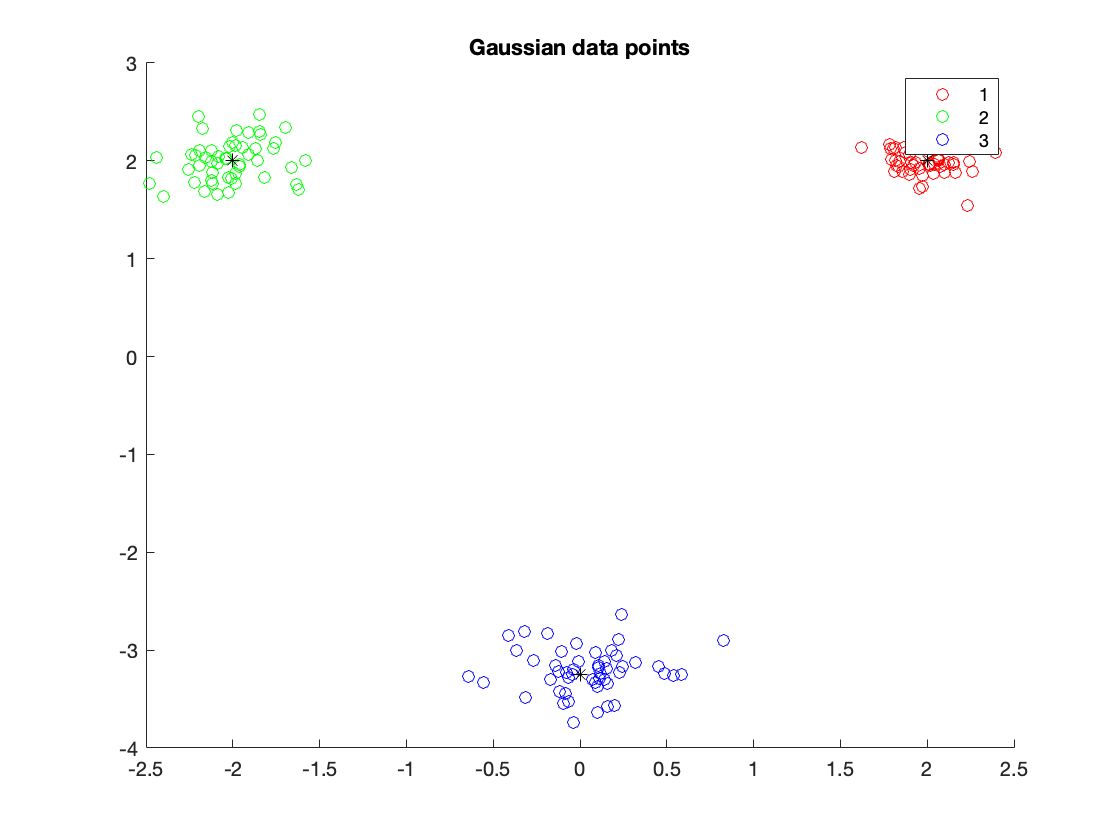

% EC 414 - HW 3 - Spring 2022
% K-Means starter code

clear, clc, close all;

%% Generate Gaussian data:
% Add code below:
mu1 = [2,2]';
mu2 = [-2,2]';
mu3 = [0, -3.25]';

I2 = [1 0; 0 1];

sigma1 = 0.02 * I2;
sigma2 = 0.05 * I2;
sigma3 = 0.07 * I2;

points = 50;

% data1 =  mu1' + randn(points,2)*sigma1;
% data2 =  mu2' + randn(points,2)*sigma2;
% data3 =  mu3' + randn(points,2)*sigma3;
data1 = mvnrnd(mu1, sigma1, points);
data2 = mvnrnd(mu2, sigma2, points);
data3 = mvnrnd(mu3, sigma3, points);

mu = [mu1'; mu2'; mu3'];
figure()
scatter(data1(:,1), data1(:,2), 'r');
hold on
scatter(data2(:,1), data2(:,2), 'g');
scatter(data3(:,1), data3(:,2), 'b');
scatter(mu(:,1),mu(:,2),'black*'); %plot mu values
title('Gaussian data points')
legend('1','2','3');
hold off

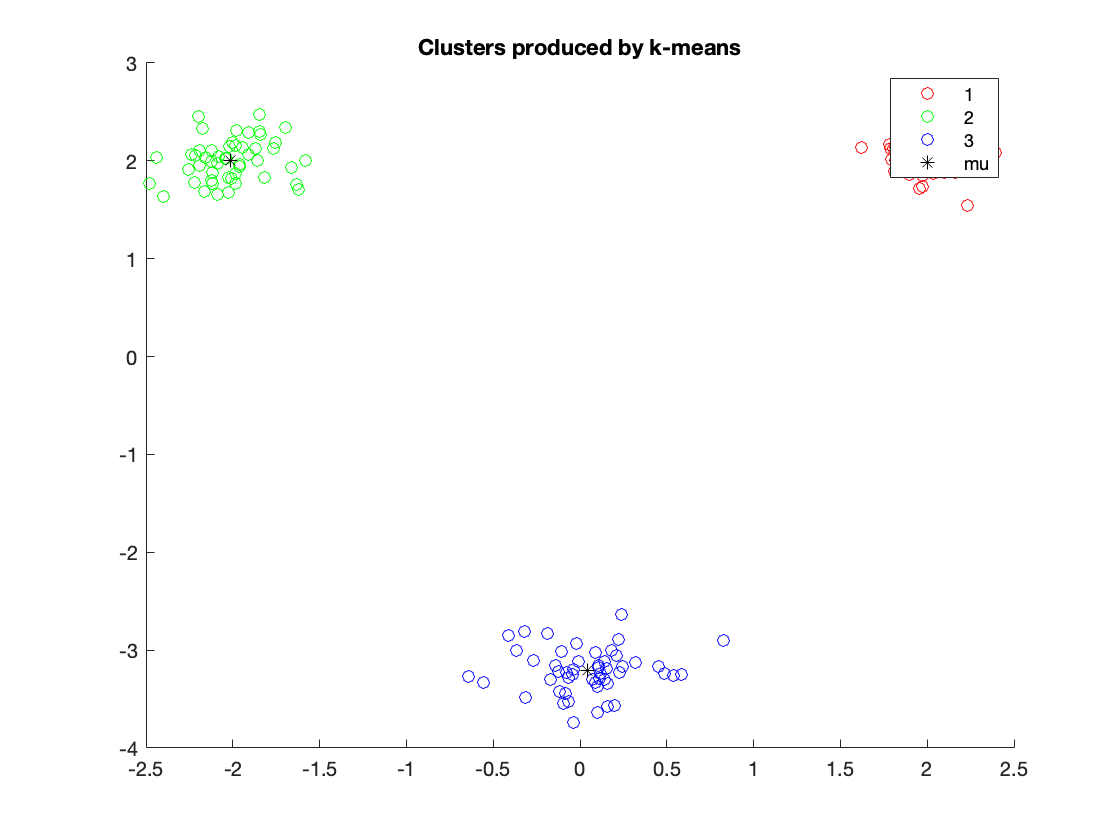


%% Generate NBA data:
% Add code below:

% HINT: readmatrix might be useful here
NBA = readmatrix("NBA_stats_2018_2019.xlsx");

% % Problem 3.2(f): Generate Concentric Rings Dataset using
% % sample_circle.m provided to you in the HW 3 folder on Blackboard.
% 
%% K-Means implementation
% Add code below

K = 3;
DATA = [data1 ; data2; data3];

%%(a)
MU_init_a = [3 3; -4 -1; 2 -4];
[MU_current_a, labels_a, WCSS_a] = k_means(K, MU_init_a, DATA);
graph_clusters(DATA, labels_a, MU_current_a);

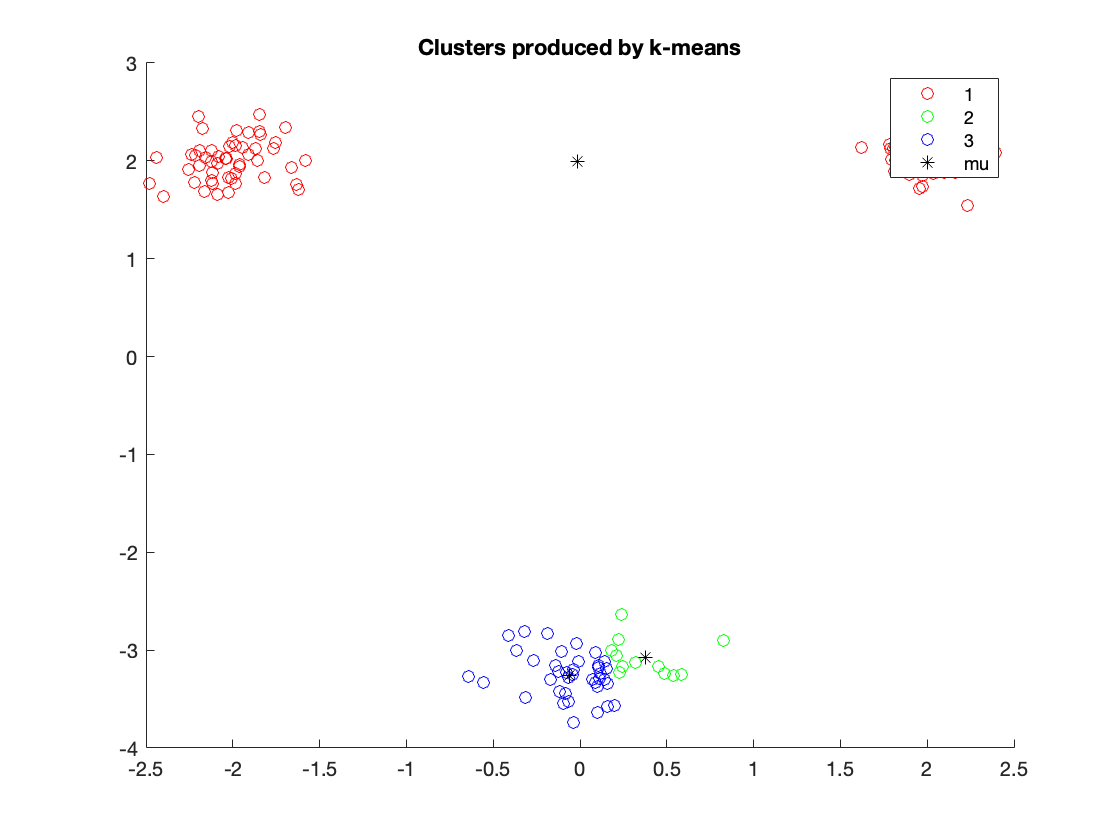


%%(b)
MU_init_b = [-0.14 2.61; 3.15 -0.84; -3.28 -1.58];
[MU_current_b, labels_b, WCSS_b] = k_means(K, MU_init_b, DATA);
graph_clusters(DATA, labels_b, MU_current_b);

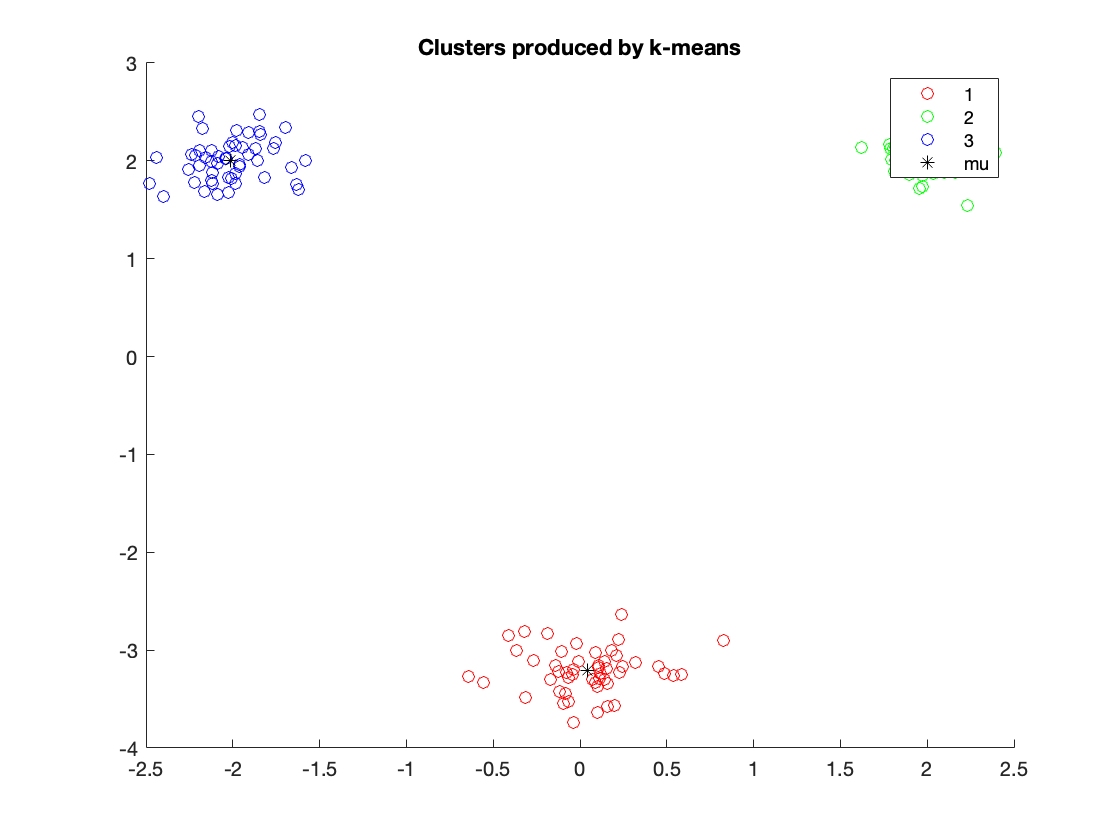


%%(c)
%We suggest choosing centers either 1) uniformly at random from the dataset or alternatively 2) uniformly distributed over a tight rectangular region encompassing the dataset.
size = length(DATA);
WCSS_c = zeros(10,1);
for(i = 1:10)
    index = randi([1,size],1,3); %generate index for three random points from data set for mu
    while(length(unique(index)) ~= 3) %if indices are not all unique keep generating indices
        index = randi([1,size],1,3);
    end
    c(i).MU_init = DATA(index, :); %get initial mu values from dataset using randomly generated indices
    [c(i).MU_current, c(i).labels, c(i).WCSS] = k_means(K, c(i).MU_init, DATA);
    %graph_clusters(DATA, c(i).labels, c(i).MU_current);
    WCSS_c(i) = c(i).WCSS;
end
sort_WCSS = sort(WCSS_c); %sort WCSS from smallest value to largest value
i = find(sort_WCSS(1) == WCSS_c); %find the index of the smallest WCSS
i = i(1); %if multiple mu values generate the smallest WCSS, choose the first one
graph_clusters(DATA, c(i).labels, c(i).MU_current); %graph clusters of smallest WCSS

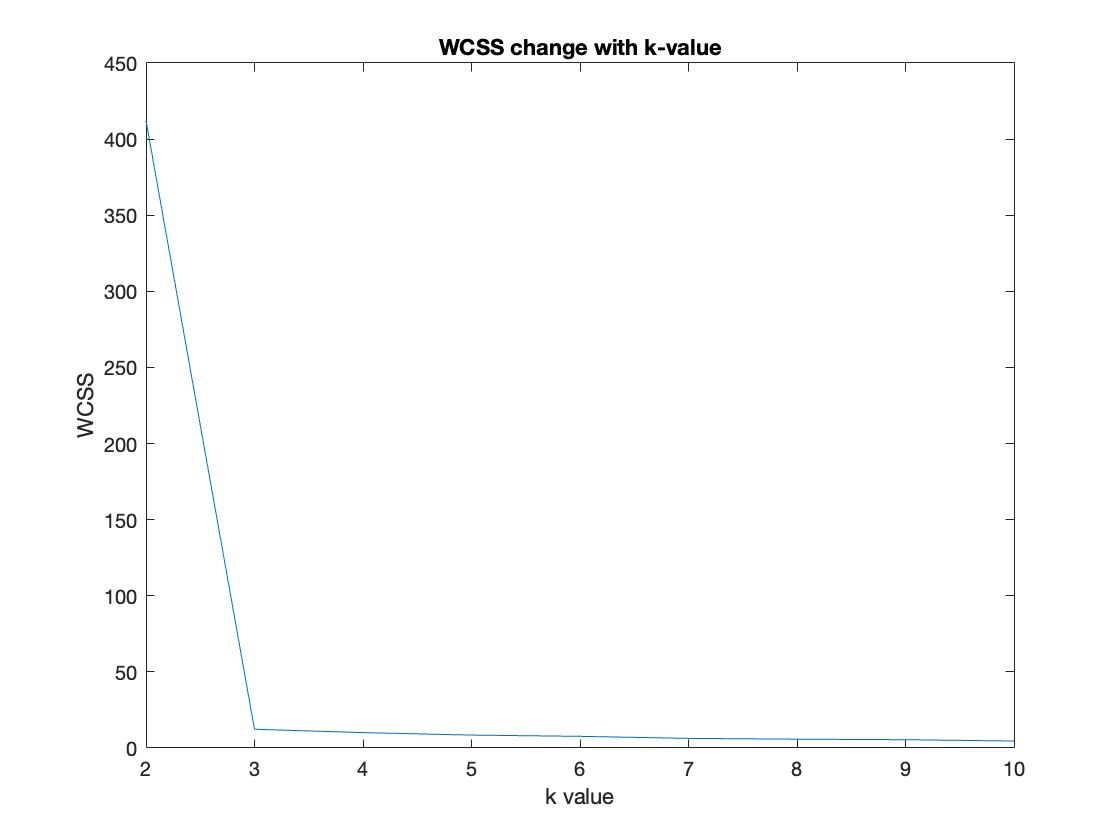



%%(d)
size = length(DATA);
WCSS_d = zeros(9,1);
for(K = 2:10)
    for(i = 1:10)
        index = randi([1,size],1,K); %generate index for three random points from data set for mu
        while(length(unique(index)) ~= K) %if indices are not all unique keep generating indices
            index = randi([1,size],1,K);
        end
        k(K-1).d(i).MU_init = DATA(index, :); %get initial mu values from dataset using randomly generated indices
        [k(K-1).d(i).MU_current, k(K-1).d(i).labels, k(K-1).d(i).WCSS] = k_means(K, k(K-1).d(i).MU_init, DATA);
        %graph_clusters(DATA, d(i).labels, d(i).MU_current);
        k(K-1).WCSS(i) = k(K-1).d(i).WCSS;
    end
    sort_WCSS = sort(k(K-1).WCSS); %sort WCSS from smallest value to largest value
    WCSS_d(K-1) = sort_WCSS(1);
end
figure()
plot(2:10, WCSS_d)
xlabel('k value')
ylabel('WCSS')
title('WCSS change with k-value')

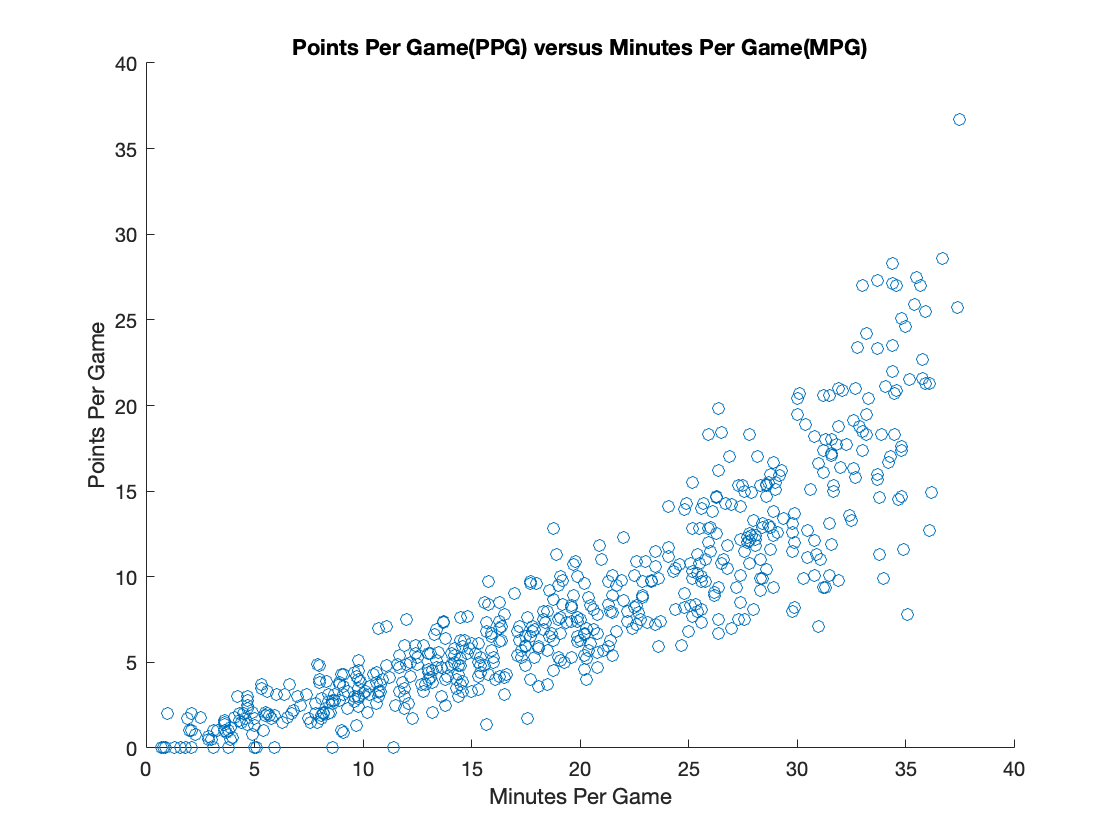


%%(e)
PPG = NBA(:,7);
MPG = NBA(:,5);
DATA = [MPG PPG];

%plot data
figure()
scatter(MPG, PPG);
xlabel('Minutes Per Game')
ylabel('Points Per Game')
title('Points Per Game(PPG) versus Minutes Per Game(MPG)')

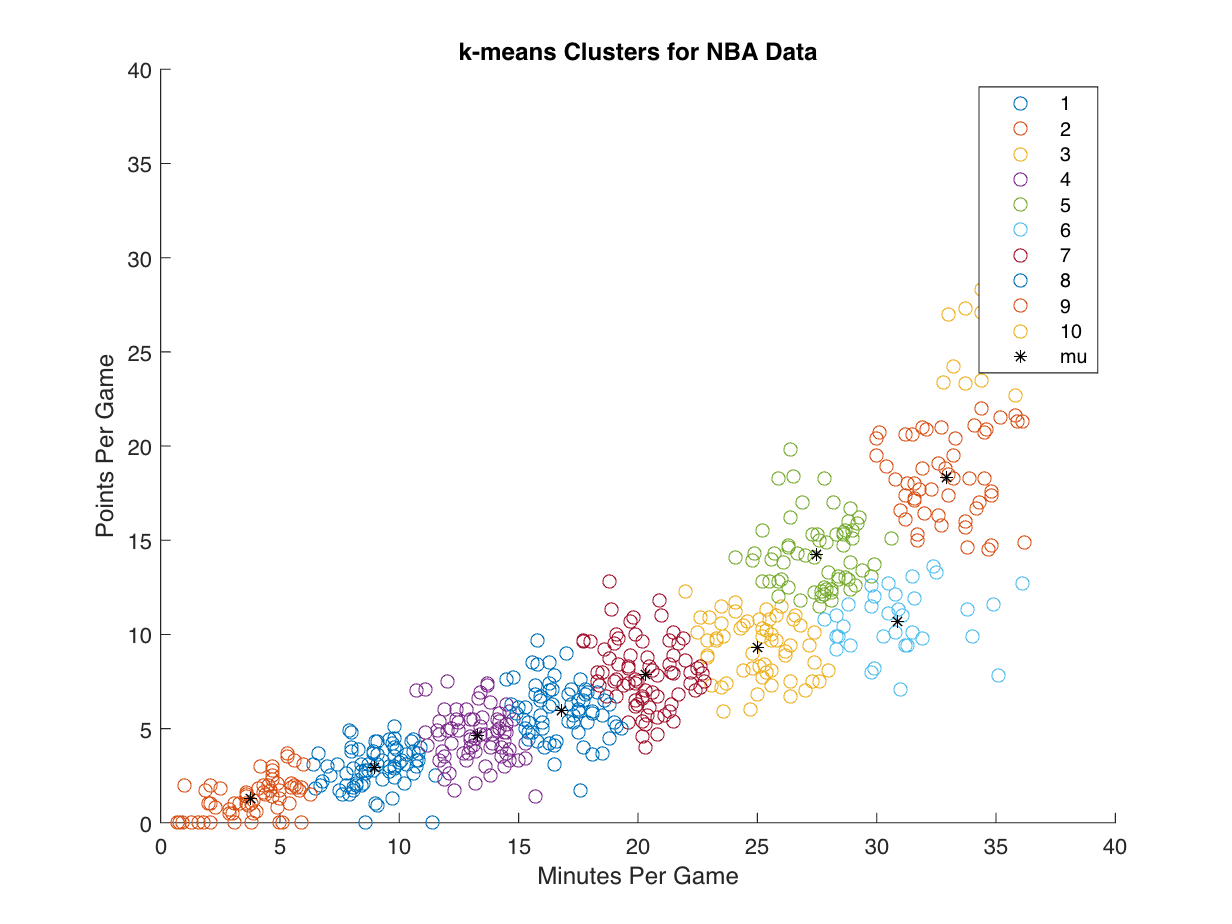


%Apply your implementation of the k-means algorithm with k = 10 selecting the best of 10 different random initializations as the final outpu
K = 10;
size = length(DATA);
WCSS_e = zeros(10,1);
for(i = 1:10)
    index = randi([1,size],1,K); %generate index for three random points from data set for mu
    while(length(unique(index)) ~= K) %if indices are not all unique keep generating indices
        index = randi([1,size],1,K);
    end
    e(i).MU_init = DATA(index, :); %get initial mu values from dataset using randomly generated indices
    [e(i).MU_current, e(i).labels, e(i).WCSS] = k_means(K, e(i).MU_init, DATA);
    %graph_clusters(DATA, c(i).labels, c(i).MU_current);
    WCSS_e(i) = e(i).WCSS;
end
sort_WCSS = sort(WCSS_e); %sort WCSS from smallest value to largest value
ind = find(sort_WCSS(1) == WCSS_e); %find the index of the smallest WCSS
ind = ind(1); %if multiple mu values generate the smallest WCSS, choose the first one
%graph_clusters(DATA, e(i).labels, e(i).MU_current); %graph clusters of smallest WCSS
figure()
data_i = DATA(find(e(ind).labels == 1), :);
scatter(data_i(:,1), data_i(:,2)); %plot points with label 1
hold on
for(i = 2:10)
    data_i = DATA(find(e(ind).labels == i), :);
    scatter(data_i(:,1), data_i(:,2));
end
scatter(e(ind).MU_current(:,1),e(ind).MU_current(:,2),'black*')
xlabel('Minutes Per Game')
ylabel('Points Per Game')
title('k-means Clusters for NBA Data')
legend({'1','2','3','4','5','6','7','8','9','10','mu'})
hold off

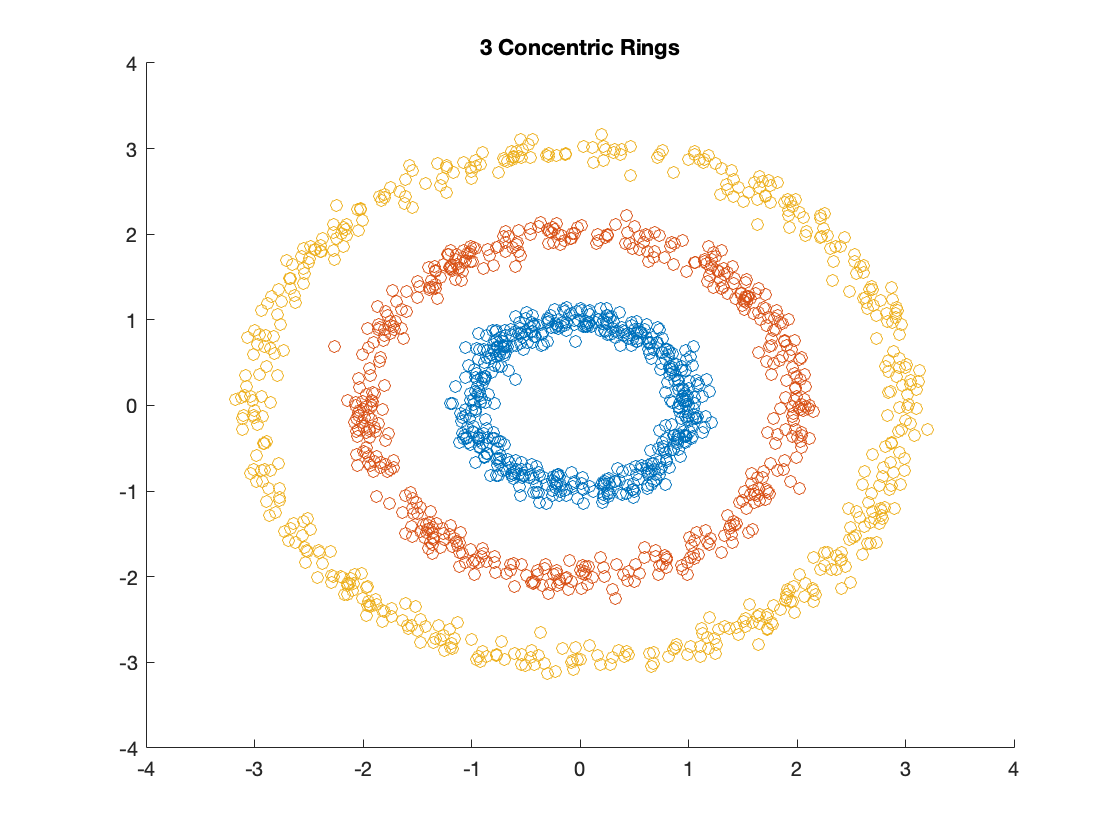


%%(f)
DATA = sample_circle(3);
scatter(DATA(1:500, 1), DATA(1:500, 2))
hold on
scatter(DATA(501:1000, 1), DATA(501:1000, 2))
scatter(DATA(1001:1500, 1), DATA(1001:1500, 2))
title('3 Concentric Rings')
hold off

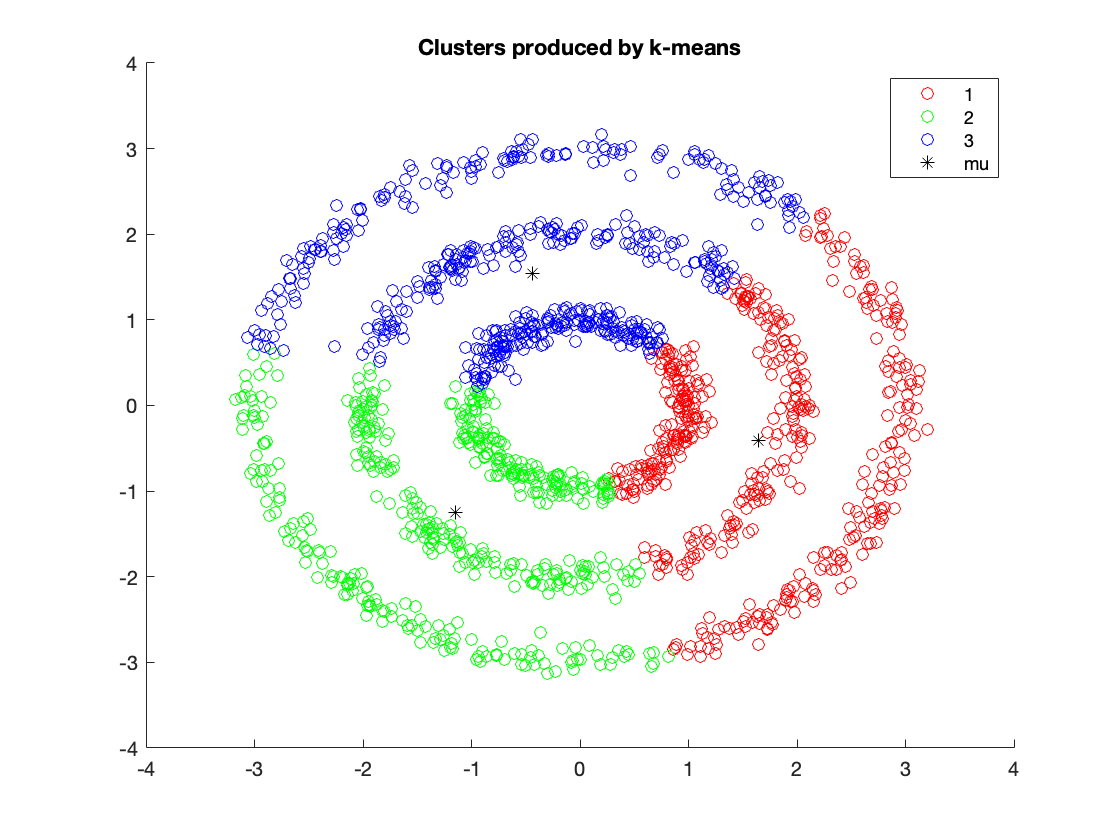


K = 3;
size = length(DATA);
WCSS_f = zeros(10,1);
for(i = 1:10)
    index = randi([1,size],1,K); %generate index for three random points from data set for mu
    while(length(unique(index)) ~= K) %if indices are not all unique keep generating indices
        index = randi([1,size],1,K);
    end
    f(i).MU_init = DATA(index, :); %get initial mu values from dataset using randomly generated indices
    [f(i).MU_current, f(i).labels, f(i).WCSS] = k_means(K, f(i).MU_init, DATA);
    %graph_clusters(DATA, c(i).labels, c(i).MU_current);
    WCSS_f(i) = f(i).WCSS;
end
sort_WCSS = sort(WCSS_f); %sort WCSS from smallest value to largest value
i = find(sort_WCSS(1) == WCSS_f); %find the index of the smallest WCSS
i = ind(1); %if multiple mu values generate the smallest WCSS, choose the first one
graph_clusters(DATA, f(i).labels, f(i).MU_current); %graph clusters of smallest WCSS



%returns euclidean distance of a singular point to each point in a matrix

function distance = euclidean_distance(point, points)
    distance = zeros(length(points),1); %initialize distance vector
    [r,c] = size(points);
    for (i = 1:r) % loop through each point of the matrix of points
        distance(i,1) = sqrt((point(1,1)-points(i,1))^2+(point(1,2)-points(i,2))^2); %distance between two points
    end
end

%returns the label of the closest point given a distance vector and matrix of points
function label = closest_label(distance, points)
    sort_dist = sort(distance); %sort the distance vector from smalllest to largest
    close_point = points(find(sort_dist(1) == distance), :); %find the index of the smallest distance in the distance vector and find point that gives that distance
    [tf, label] = ismember(close_point, points, 'rows'); %find row index of the closest mu, correlates to label
    label = label(1); %if there is a tie in the distance choose the first label
end

%creates a scatter plot of the clusters created and their mu values given the data points, label of those points, and mu values
function graph_clusters(data, labels, mu)
    data1 = data(find(labels == 1), :);
    data2 = data(find(labels == 2), :);
    data3 = data(find(labels == 3), :);
    
    figure()
    scatter(data1(:,1), data1(:,2), 'r'); %plot points with label 1
    hold on
    scatter(data2(:,1), data2(:,2), 'g'); %plot points with label 2
    scatter(data3(:,1), data3(:,2), 'b'); %plot points with label 3
    scatter(mu(:,1),mu(:,2),'black*'); %plot mu values
    title('Clusters produced by k-means')
    legend('1','2','3','mu');
    hold off
end

%takes K value, initial values of mu, and the data set
%returns the final mu values after k_means has converged
%returns the labels of each data point
%returns the WCSS after convergence
function [MU_current, labels, WCSS] = k_means(K, MU_init, DATA)
    MU_previous = MU_init;
    MU_current = MU_init;
    
    % initializations
    
    labels = ones(length(DATA),1);
    converged = 0;
    iteration = 0;
    convergence_threshold = 0.025;
    
    %stop if the derived cluster means become stationary
    while (converged==0)
        iteration = iteration + 1;
        %fprintf('Iteration: %d\n',iteration)
    
        %% CODE - Assignment Step - Assign each data observation to the cluster with the nearest mean:
        % Write code below here:
        for(i = 1:length(DATA))
            dist = euclidean_distance(DATA(i,:),MU_current); %find euclidean distance of each data point to each mu
            labels(i) = closest_label(dist, MU_current); %find the label of the closest mu       
        end
        %% CODE - Mean Updating - Update the cluster means
        % Write code below here:
        MU_previous = MU_current;
        
        for(i = 1:K) %loop through each label
            label = DATA(find(labels == i),:); %find all data points with that label 
            if(~isempty(label)) %check if cluster is not empty
                MU_current(i,:) = mean(label); %find mean of data points with label and update current mu
            end
        end
        %% CODE 4 - Check for convergence 
        % Write code below here:
        
        %check if the change between the previous mu and the current mu is smaller than the threshhold, if it is k-means has converged
        if (abs(MU_previous - MU_current) < convergence_threshold)
            converged=1;
        end  
        %% CODE 5 - Plot clustering results if converged:
        % Write code below here:
        if (converged == 1)
            %fprintf('\nConverged.\n')
          
            %% If converged, get WCSS metric
            % Add code below
            WCSS = 0;
            for(i = 1:K) %loop through each label
                dist = euclidean_distance(MU_current(i,:), DATA(find(labels == i),:)); %find all data points with that label
                WCSS = WCSS + sum(dist.^2);
            end
        end
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end